# Math 155 Final Project

Joy Liu

clear;clc;close all;

## Artificial Painting Toolbox - Monet style

% Read in image
f = imread('projectimg3.tiff');
fs = imread('projectimg3s.tiff'); % smaller image for gradient manipulation

% Recast as a double
I = double(f);
Is = double(fs);

% Prepare intensity image of original color image
I1 = (1/3) * (I(:,:, 1) + I(:,:,2) + I(:,:,3));
I1s = (1/3) * (Is(:,:, 1) + Is(:,:,2) + Is(:,:,3));

I2 = blur(I1, 50);
I2s = blur(I1s, 50);


% Apply Sobel kernals to intensity image
gx = [-1, -2, -1; 0, 0, 0; 1, 2, 1];
gy = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
Gx = imgconvolution(I2,gx);
Gy = imgconvolution(I2,gy);
I2 = (Gx.^2 + Gy.^2).^(0.5);

I2d = (imgconvolution(I1,gx).^2 + imgconvolution(I1,gy).^2).^(0.5);
Gxs = imgconvolution(I2s,gx);
Gys = imgconvolution(I2s,gy);

Gxold = Gx;
Gyold = Gy;

% Modify Gx and Gy
vals = zeros(2, size(I2s,1)*size(I2s,2)/10);
centers = zeros(2,size(I2s,1)*size(I2s,2)/10);
lowcenters = zeros(2,size(I2s,1)*size(I2s,2));
k = 1;
l = 1;
for i = 1:size(I2s,1)
     for j = 1:size(I2s,2)
         if abs(Gxs(i,j)) < 3 || abs(Gys(i,j)) < 3
            Gxs(i,j) = 0;
            Gys(i,j) = 0;
            lowcenters(1,l) = i;
            lowcenters(2,l) = j;
            l = l+1;
         end
         if Gxs(i,j) * Gys(i,j) > 0
             centers(1,k) = i;
             centers(2,k) = j;
             vals(1,k) = Gxs(i,j);
             vals(2,k) = Gys(i,j);
             k = k+1;   
         end

     end
end

st = tpaps(centers, vals);

avals = fnval(st,lowcenters);

Gxnew = zeros(size(Gxs));
Gynew = zeros(size(Gys));
for i = 1:size(lowcenters,2)
   if (lowcenters(1,i) == 0)
       break
   end
   Gxnew(lowcenters(1,i),lowcenters(2,i)) = avals(1,i);
   Gynew(lowcenters(1,i),lowcenters(2,i)) = avals(2,i);
end

r = size(f,1)/size(fs,1); % how scaled down the image is
for i=1:size(Gxnew,1)
    for j=1:size(Gxnew,1)
        if Gxnew(i,j) ~= 0
            Gx(1+r*(i-1):r*i,1+r*(j-1):r*j) = Gxnew(i,j);
            Gy(1+r*(i-1):r*i,1+r*(j-1):r*j) = Gynew(i,j);
        end
    end
end


%% Stroke generation
I3 = zeros(size(I));
sp = 2; % stroke spacing
maxlength = 50;
for i = 1:sp:size(I2,1)
    for j = 1:sp:size(I2,2)
       % Gradient direction to determine angle of stroke 
       d = atan(Gx(i,j)/(Gy(i,j) + .001)) + pi/2;
       dirx = cos(d) + 0.5*rand; % angle pertubation
       diry = sin(d) + 0.5*rand;
       a = endpts(i, j, dirx, diry, maxlength, I2);
       
       p1 = [round(a(1)), round(a(2))];
       n = 1;
       col = 20*rand;  % intensity pertubation
       while p1(1)~=round(a(3)) && p1(2)~=round(a(4))
            I3(p1(1):p1(1)+1, p1(2)-1:p1(2), 1) = I(i,j,1)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*20*rand;
            I3(p1(1):p1(1)+1, p1(2)-1:p1(2), 2) = I(i,j,2)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*20*rand;
            I3(p1(1):p1(1)+1, p1(2)-1:p1(2), 3) = I(i,j,3)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*20*rand;
            p1(1) = round(a(1) - n * (dirx));
            p1(2) = round(a(2) - n * (diry));
            n = n + 1;
       end
    end
end

%% Stroke generation without modified gradient
I3old = zeros(size(I));
sp = 2; % stroke spacing
maxlength = 50;
for i = 1:sp:size(I2,1)
    for j = 1:sp:size(I2,2)
       % Gradient direction to determine angle of stroke 
       d = atan(Gxold(i,j)/(Gyold(i,j) + .001)) + pi/2;
       dirx = cos(d) + 0.5*rand; % angle pertubation
       diry = sin(d) + 0.5*rand;
       a = endpts(i, j, dirx, diry, maxlength, I2);
       
       p1 = [round(a(1)), round(a(2))];
       n = 1;
       col = 10*rand;  % intensity pertubation
       while p1(1)~=round(a(3)) && p1(2)~=round(a(4))
            I3old(p1(1):p1(1)+1, p1(2)-1:p1(2)+1, 1) = I(i,j,1)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*25*rand;
            I3old(p1(1):p1(1)+1, p1(2)-1:p1(2)+1, 2) = I(i,j,2)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*25*rand;
            I3old(p1(1):p1(1)+1, p1(2)-1:p1(2)+1, 3) = I(i,j,3)+(-1)^(round(col*10))*col+(-1)^(round(rand*10))*25*rand;
            p1(1) = round(a(1) - n * (dirx));
            p1(2) = round(a(2) - n * (diry));
            n = n + 1;
       end
    end
end

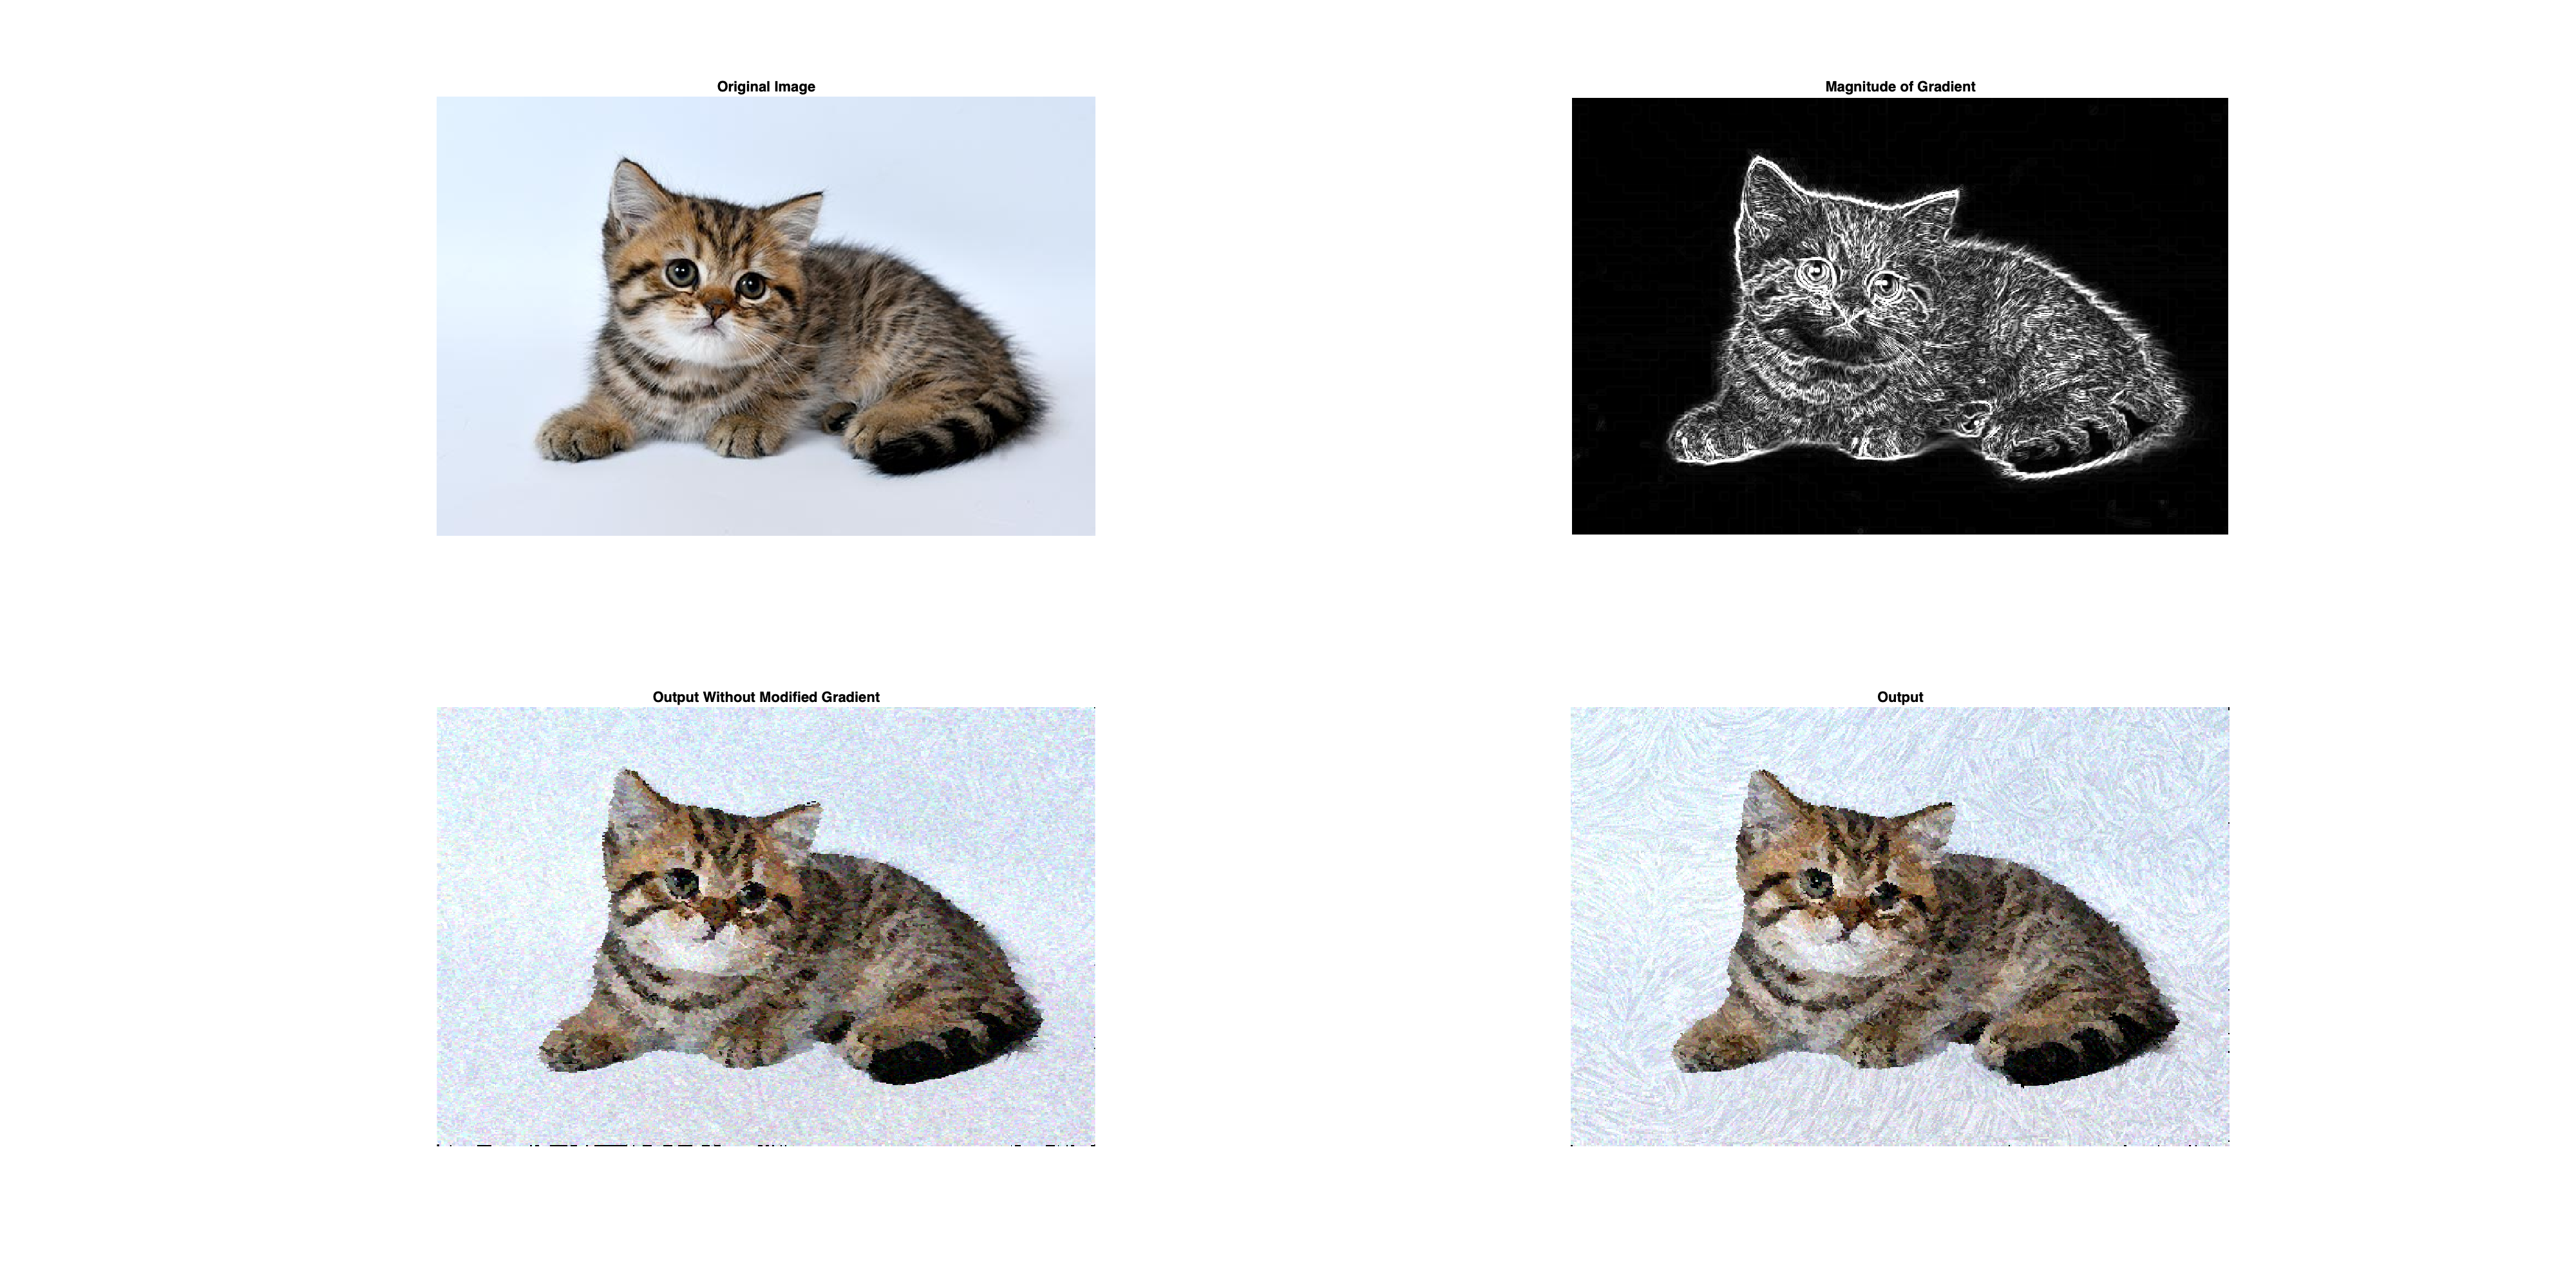

% Post processing
I3 = I3(1:size(I2,1),1:size(I2,2),1:3);
% I3old = I3old(1:size(I2,1),1:size(I2,2),1:3);
%interior
for i = 2:size(I2,1)-1 
    for j = 2:size(I2,2)-1
        if I3(i,j,1) + I3(i,j,2) + I3(i,j,3) == 0
            for p = i-1:i+1
                for q = j-1:j+1
                    if I3(p,q,1) + I3(p,q,2) + I3(p,q,3) ~= 0
                        I3(i,j,1) = I3(p,q,1);
                        I3(i,j,2) = I3(p,q,2);
                        I3(i,j,3) = I3(p,q,3);
                    end
                end
            end
        end
        if I3old(i,j,1) + I3old(i,j,2) + I3old(i,j,3) == 0
            for p = i-1:i+1
                for q = j-1:j+1
                    if I3old(p,q,1) + I3old(p,q,2) + I3old(p,q,3) ~= 0
                        I3old(i,j,1) = I3old(p,q,1);
                        I3old(i,j,2) = I3old(p,q,2);
                        I3old(i,j,3) = I3old(p,q,3);
                    end
                end
            end
        end
    end
end
% top
for j = 1:size(I2,2)
    if I3(1,j,1) + I3(1,j,2) + I3(1,j,3) == 0
        I3(1,j,1) = I3(2,j,1);
        I3(1,j,2) = I3(2,j,2);
        I3(1,j,3) = I3(2,j,3);
    end
    if I3old(1,j,1) + I3old(1,j,2) + I3old(1,j,3) == 0
        I3old(1,j,1) = I3old(2,j,1);
        I3old(1,j,2) = I3old(2,j,2);
        I3old(1,j,3) = I3old(2,j,3);
    end
end
% left
for i = 1:size(I2,1)
    if I3(i,1,1) + I3(i,1,2) + I3(i,1,3) == 0
        I3(i,1,1) = I3(i,2,1);
        I3(i,1,2) = I3(i,2,2);
        I3(i,1,3) = I3(i,2,3);
    end
    if I3old(i,1,1) + I3old(i,1,2) + I3old(i,1,3) == 0
        I3old(i,1,1) = I3old(i,2,1);
        I3old(i,1,2) = I3old(i,2,2);
        I3old(i,1,3) = I3old(i,2,3);
    end
end

figure
set(gcf,'Position',[10,10,2000,1000])

% Original Image
subplot(2,2,1)
imshow(uint8(f))
title('Original Image')

% Magnitude of Gradient
subplot(2,2,2)
imshow(uint8(I2d))
title('Magnitude of Gradient')

% Output without modified gradient
subplot(2,2,3)
imshow(uint8(I3old))
title('Output Without Modified Gradient')

% Output Image
subplot(2,2,4)
imshow(uint8(I3))
title('Output')
saveas(gcf,'Project_Results.png')

## Functions

Blurring in Frequency Domain

function g = blur(I, d)
f = I;
I = padarray(I, size(I), 'post'); % 1) Pad Image

% 2) Prepare image for DFT will be centered
for i=1:size(f,1)
    for j=1:size(f,2)
        I(i,j) = (-1)^(i+j) * I(i,j); 
    end
end

% 3) Compute DFT
I = fft2(I); 

% 4) Construct H(u,v)
H = zeros(size(I));
D0 = d; % Cutoff frequency
for i=1:size(I,1)
    for j=1:size(I,2)
        D = sqrt((i - size(I,1)/2)^2 + (j - size(I,2)/2)^2);
        H(i,j) = exp(-D^2 / (2 * D0^2));
    end
end

% 4) Compute H(u,v)F(u,v)
I = I.*H;

% 5) Compute IDFT = g(x,y)
I = real(ifft2(I));

% 6) Compute (-1)^(x+y) * g(x,y)
for i=1:size(f,1)
    for j=1:size(f,2)
        I(i,j) = (-1)^(i+j) * I(i,j); 
    end
end

% 7) Crop back to original
g = I(1:size(f,1), 1:size(f,2));
end

Image Convolution

function g = imgconvolution(f, w)
% function to perform convolution of a kernel w with an image f

kernal_size = size(w);
a = kernal_size(1);
b = kernal_size(2);

image_size = size(f);
X = image_size(1);
Y = image_size(2);

g = zeros(size(f)); % intialize output array
f1 = padarray(f, [(a - 1)/2, (a - 1)/2,]); % pad the image according to size of kernal

for x = 1:X
    for y = 1:Y
        for i = 1:a
            for j = 1:b
                g(x, y) = g(x, y) + (w(i, j) * f1(x + i - 1, y + j - 1));
            end
        end
    end
end
end

Determining stroke endpoints

function a = endpts(cx, cy, dirx, diry, maxlength, I)
I = padarray(I, [maxlength, maxlength]);

x1 = cx + maxlength;
y1 = cy + maxlength;
lastSample = I(x1, y1);
tempx = x1 + dirx;
tempy = y1 + diry;

while norm([cx + maxlength, cy + maxlength]-[tempx,tempy]) < maxlength/2
    tempx = x1 + dirx;
    tempy = y1 + diry;
    tx = max(1, round(tempx));
    ty = max(1, round(tempy));
    newSample = I(tx, ty);
    
    if newSample < lastSample - 0.08
        break
    end
    x1 = tempx;
    y1 = tempy;
    lastSample = newSample;
end

x2 = cx + maxlength;
y2 = cy + maxlength;
lastSample = I(x2, y2);
tempx = x2 - dirx;
tempy = y2 - diry;

while norm([cx + maxlength, cy + maxlength]-[tempx,tempy]) < maxlength/2
    tempx = x2 - dirx;
    tempy = y2 - diry;
    tx = max(1, round(tempx));
    ty = max(1, round(tempy));
    newSample = I(tx, ty);
    
    if newSample < lastSample - 0.08
        break
    end
    x2 = tempx;
    y2 = tempy;
    lastSample = newSample;
end

a = [x1-maxlength, y1-maxlength, x2-maxlength, y2-maxlength];
end